# Design of PID regulator with pole cancellation technique

This live script needs the control toolbox. 

The script goes through the main principles of the design of P (proportional), PI (proportional plus integral), PD (proportional and derivative) and PID (proportional plus integral plus derivative), or rather PIPD (serially connected PI and PD) controllers. The controllers are designed for the model of the process to fulfil given performance specifications.

Here for controller design a **pole cancellation technique** is presented. Pole cancellation technique means that the controller with its zeros cancels the unfavourable poles of the model of the system and introduces favourable poles instead fulfilling the quality specifications set for the control system. In the design process frequency domain considerations are taken into account.

Alternative cotnrol design procedures are also given in the files: ***proportional_design_with_bode.mlx,***  ***lag_design_with_bode.mlx,*** ***lead_design_with_bode.mlx, lead_lag_design_with_bode.mlx .***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by Gyula Max and Ruth Bars, Budapest University of Technology and Economics

**Reference****: Control Engineering **and** Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**

                                                          

Referred files were written by J.A. Rossiter, University of Sheffield                             

These notes give the engineering and analytical background alongside some simple MATLAB code snippets that can be used for equivalent analysis.

## Table of contents

- PID controllers

- Quality specifications

- Design of PID controllers considering pole cancellation

- Ilustrative Examples

## 1. PID controllers: background and definitions

Consider the closed loop control system shown in the figure below, which contains the transfer function G(s) of the process (plant) to be controlled and the transfer function M(s) of the controller.

 

- In the sequel the most important specifications are formulated, then some procedures for controller design are shown.  

- For the given process a series controller is to be designed which ensures the fulfilment of the quality specifications.

- In practice the most frequently used controller is the PID controller. 

A PID controller consists of parallel connected proportional (P),  integrating (I) and differentiating (D) effects. In the time domain in ideal case it calculates the control signal u(t) from the error signal e(t) according to the following relationship:


$$u\left(t\right)=k_p e\left(t\right)+k_I \int_0^t e\left(\tau \right)d\tau +k_D \frac{\textrm{de}\left(t\right)}{\textrm{dt}}$$


So the control signal considers a component proportional to the error signal, considers also the past history of the error signal with the integral component, and the trend of the change of the error signal with the differentiating component.

The Laplace transform of the control signal is:

 
$$U\left(s\right)=k_p E\left(s\right)+\frac{k_I }{s}E\left(s\right)+k_{D\;} \textrm{sE}\left(s\right)=\left(k_p +\frac{k_I }{s}+sk_D \right)E\left(s\right)$$


As the ideal differentiating effect is non-realizable, in practice it appears together with a small time constant *T* as follows:


$$U\left(s\right)=\left(k_p +\frac{k_I }{s}+\frac{sk_D }{1+\textrm{sT}}\right)E\left(s\right)$$


If only the proportional part is applied, a so called P controller is realized. If only the integrating part is used, I controller is applied. With the parallel connected P and I parts we use a so-called PI controller. With the P and D parts a PD controller is given. With all the three components a PID controller is considered. 

The transfer function of the PID controller can be approximated by the following formula:

$M_{\textrm{PID}} \left(s\right)=k_p +\frac{k_I }{s}+\frac{sk_D }{1+\textrm{sT}}\approx K_p \frac{1+sT_I }{sT_I }\cdot \frac{1+sT_D }{1+\textrm{sT}}$    if $T_I >T_D >T$.

In this case we talk of serially connected PI and PD effects. This controller can be referred as a PIPD controller.

## 2. Quality specifications/performance requirements

The following requirements are set for a closed loop control system:

- Stability 

- Static response (tolerated steady state error for reference signal tracking and in disturbance rejection) 

- Properties of the transient response (overshoot of the output signal, settling time)

- Robustness

- Limitation of the maximum value of the control signal

These specifications can be formulated in the time domain and also in the frequency domain. Controller design will be executed considering the requirements formulated in the frequency domain. Some specifications do not take a major role in the design, although they are monitored.

- Stability is discussed in more detail in a separate file. In the frequency domain generally it is ensured by design for an appropriate phase margin (see below). 

- Robustness means that the behaviour of the control system is acceptable even if the parameters of the plant differ in some extent from those of the considered model of the system. This aspect is not analysed here but designers would usually assess  carefully during the design.

- The maximum value of the control signal should be kept under the limit value of the control (actuating) signal which is restricted by the physical realisation of the actuator. Reaching the limit value has a non-linear effect in the behaviour of the control system. In this case a redesign of the controller parameters would be required.

(For more on specifications see  the related files   ***proportional_design_with_bode.mlx,***  ***lag_design_with_bode.mlx,*** ***lead_design_with_bode.mlx, lead_lag_design_with_bode.mlx;  ***uncomment code below and run section to open***.***)

% proportional_design_with_bode  
% lag_design_with_bode 
% lead_design_with_bode 
% lead_lag_design_with_bode

### 2.1 Dynamic response requirements

The phase margin PM denoted by $\phi$ is computed at the gain cross over (cut-off) frequency $\omega_c$ of the Bode diagram of the open loop: $\phi =\varphi \left(\omega_c \right)+{180}^{\circ }$. At the cut off frequency the absolute value of the amplitude of the open loop is unity.  If the phase margin is positive, the system is stable.

The overshoot of the step response of the closed loop  σ(%)={[vmax–v(∞)]/v(∞)}100 is related to the maximum amplification of the amplitude - frequency function of the closed loop, and also to the phase margin calculated from the frequency function of the open loop. If the phase margin is about 60°, the overshoot is expected to be about or less than 10%. The settling time $T_s$ depends on the cut-off frequency, and can be approximated as 

$\frac{3}{\omega_c }<T_s <\frac{10}{\omega_c }$.  The higher the cut-off frequency, the faster the settling time of the process. 

In summary, the frequency $\omega_c$ can be used as an implicit measure of the dynamic response time and/or the target response time $T_s$ can be represented by an equivalent $\omega_c$.

### 2.2 Static response requirements

The loop gain A and the type number i (the number of the integrators in the open loop) affect the steady-state error. The number of the  integrators in the loop can be 0, 1 or 2. 

- Without an integrator there will be steady state error for step reference input. 

- With one integrator the steady state error for step reference signal is zero, and there is a non-zero constant error for a ramp reference input. 

- With two integrators the control system can also track ramp reference signals without error and tracks quadradic references with a steady error. However stabilisation and achieving good performance are now more challenging.

- With more integrators in the loop it is unlikely that stability can be maintained.

Typically there will be a requirement for zero offset for a given signal type (e.g. constant targets) which dictates the number of integrators required and a specified offset limit for other signal types (e.g. ramps), which will lead to a steady-state gain requirement on the compensator parameters.

## 3. Design of PID controllers considering pole cancellation

The structure and the parameters of the controller have to be chosen considering the quality specifications. 

The structure of the controller can be P, PI, PD or PID (or rather PIPD).

**P controller** can be used if there are no high requirements for the static accuracy of the control system and the closed-loop behaviour can be relatively slow. If the process already contains an integrating effect then the static accuracy will be appropriate with a proportional controller.

**PI controller **is applied if accurate tracking is required in the steady state for a unit step reference signal. The integrator will ensure zero offsets to constant targets. With a PI controller the feedback loop behaviour may be slower than achieveable with more complicated compensators.

**PD controller** can be used to accelerate the control loop behaviour. This effect is achieved by transient over excitation of the system input *u(t)*, that is the output of the controller. 

**PID (**or** PIPD) controller **is applied if both the static accuracy and the speed of the control loop have to be increased.

Now a simple compensation method is shown for controller design, when the phase margin (see section 2.1) is the prescribed value or performance requirement. A usual controller design procedure is the cancellation of the unfavorable poles of the plant *G(s)* with the zeros of the controller *M(s)* and introducing appropriate poles instead.

***Remark***: *It is important to mention that it is not allowed to cancel unstable poles of the plant as no cancellation will ever be perfect, and even if it were, any other uncertainty such as input and output disturbances would result in divergent signals within the control loop which might not be immediately evident.  *

In a *PID *(or* PIPD*) controller there are 4 parameters: $K_P ,T_I ,T_D \;\textrm{and}\;T$. When designing a controller with a pole cancellation technique these parameters are chosen as follows: Let parameter $T_I$ be equal to the biggest time constant of the model of the process (the pole with the lowest frequency), and let parameter $T_D$ be equal to the second biggest time constant. Thus the zeros introduced by the controller cancel two poles of the process. Parameter $T$ is given in form $T$ = $T_D$/$n_p$ where $n_p$ is the ratio of pole replacement, that is,  how far the *PD* element  pushes away the compensated pole of the system. A good experimental rule is to choose the value of $n_p$ in range 2 – 10. If it is higher, the feedback loop will be faster, but at the cost of a higher maximum of the control signal (and the correspoding need for more expensive and robust actuators). As the value of parameter ***K*** does not influence the phase course of the open loop frequency function, this parameter can be used to set the value of the prescribed phase margin (e.g. see ***proportional_design_with_bode.mlx)***. In this way the approximate Bode amplitude diagram of the open loop will have a slope close to -20dB/decade in a quite long range around the cut-off frequency.

The reader is reminded that  the cancellation is between *M(s)* and *G(s)*, but the dynamics of the plant *G(s)* still exist and may become evident in reponse to, for example,  input disturbances. The use of ***minreal.m*** could be removed from the code below to better reflect an actual implementation and avoid hiding cancellations which may occur only approximately in practice.

## **4. Ilustrative Examples**

#### 4.1 Controller design for a third order proportional process

The transfer function of the process is


$$G\left(s\right)=\frac{2}{\left(1+10s\right)\left(1+s\right)\left(1+0\ldotp 2s\right)}$$


Design P, PI, PD and PIPD controllers for the process ensuring a 60° phase margin using a pole cancellation technique. Show the output and the control signals for a unit step reference target.

#### 4.1.1. Design a P proportional controller (M) for the process (G)

disp('DESIGN OF PROPORTIONAL CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS')

DESIGN OF PROPORTIONAL CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS




s=zpk('s');
disp('The process')

The process


G=2/((1+10*s)*(1+s)*(1+0.2*s))

G =
 
           1
  -------------------
  (s+0.1) (s+1) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


endtime = 20;

[mag,phase,w]=bode(G);
Gm=margin(mag,phase-60,w);  % Nice trick to find Gain (1/Gm) where phase = -120
disp('The controller giving a 60 degree PM is')

The controller giving a 60 degree PM is


M=Gm

M = 3.7579

% The loop transfer function L=MG
L=M*G;
%Check the phase margin is about 60 as desired'
disp('Check the phase margin is about 60 as desired')

Check the phase margin is about 60 as desired


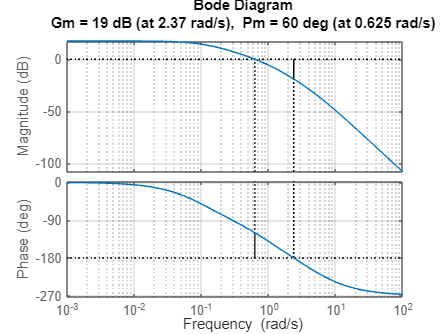

margin(L),grid

Lkp=L;


%The closed loop T=L/(1+L)
disp('The transfer function of the closed loop')

The transfer function of the closed loop


T=minreal(L/(1+L),0.001)

T =
 
                3.7579
  ----------------------------------
  (s+5.177) (s^2 + 0.9228s + 0.8224)
 
Continuous-time zero/pole/gain model.
Model Properties


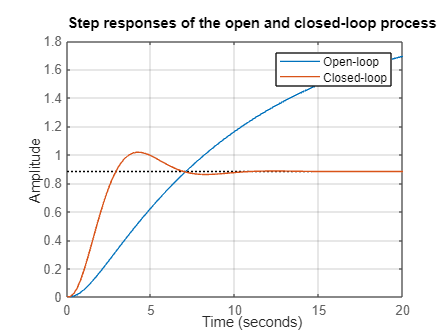


% Output responses and data
t=linspace(0,endtime,101);
step(G,T,t),grid
title('Step responses of the open and closed-loop process');
legend('Open-loop','Closed-loop')

yp=step(T,t);
steadyerr=1/(1+2*Gm);
disp(['settling time is about 10sec']);

settling time is about 10sec


disp(['steady state error = ',num2str(steadyerr)])

steady state error = 0.11743


disp('The control signal peaks well above the steady-state value resulting in a fast transient')

The control signal peaks well above the steady-state value resulting in a fast transient


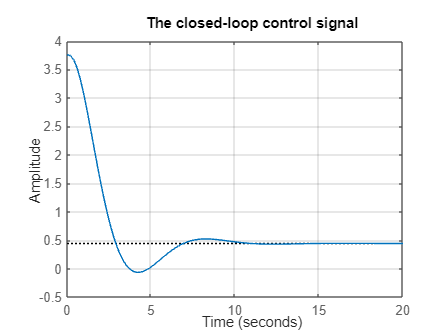


%Calculate the control signal
U=M/(1+L);
step(U,t),grid
title('The closed-loop control signal')

It is seen that the output of the control system is settled with a small overshoot, but there is a deviation from the required steady state output. The higher is the gain of the controller, the smaller is the steady state error, but the phase margin would be decreased causing oscillations.

#### 4.1.2 Design a PI controller (M) for the same process (G) 

A PI compensator includes a zero so we can use this flexibility to cancel the slowest pole in the system as shown in the code below. The remaining d.o.f. is used to ensure a 60 degree phase margin. Because the compensator includes an integral, simple offset criteria are met automatically.

disp('DESIGN OF PI CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS')

DESIGN OF PI CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS


s=zpk('s');
disp('The process')

The process


G=2/((1+10*s)*(1+s)*(1+0.2*s))

G =
 
           1
  -------------------
  (s+0.1) (s+1) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('Pole cancellation technique')

Pole cancellation technique


disp('The biggest time constant is cancelled and an integrating effect is introduced instead.')

The biggest time constant is cancelled and an integrating effect is introduced instead.


disp('The phase margin is set to ~60° by the gain of the controller.')

The phase margin is set to ~60° by the gain of the controller.


Ki=1;
M=Ki*(1+10*s)/(10*s);  % Note the choice of time constant 10 to cancel the slow pole in the system
L=minreal(M*G,0.001);

% Find and confirm the gain which gives a 60 degree PM
disp('Choice of gain to give a 60 degree PM')

Choice of gain to give a 60 degree PM


[mag1,phase,w]=bode(L);
Ki=margin(mag1,phase-60,w)

Ki = 2.5437

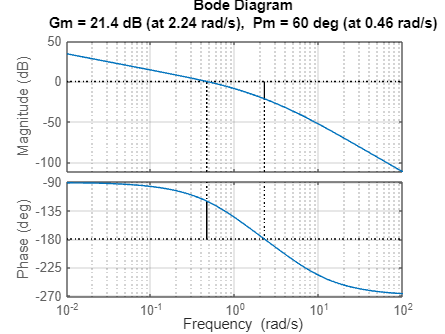

margin(L*Ki),grid


disp('The PI controller M and loop transfer function L = MG: (note the slow mode has been removed)')

The PI controller M and loop transfer function L = MG: (note the slow mode has been removed)


M=Ki*M 

M =
 
  2.5437 (s+0.1)
  --------------
        s
 
Continuous-time zero/pole/gain model.
Model Properties


L = L*Ki

L =
 
     2.5437
  -------------
  s (s+1) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


Lpi=L;


%The closed loop behaviour
disp('The closed-loop transfer function T ')

The closed-loop transfer function T 


T=minreal(L/(1+L),0.001)

T =
 
                2.5437
  ----------------------------------
  (s+5.121) (s^2 + 0.8794s + 0.4968)
 
Continuous-time zero/pole/gain model.
Model Properties


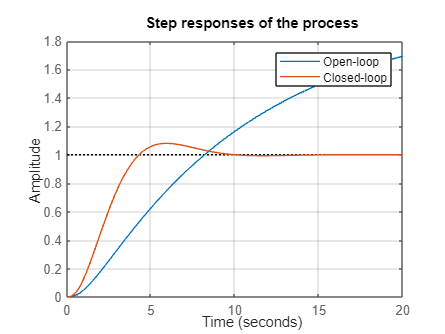

t=linspace(0,endtime,101);
yi=step(T,t);
step(G,T,t),grid
title('Step responses of the process');
legend('Open-loop','Closed-loop');

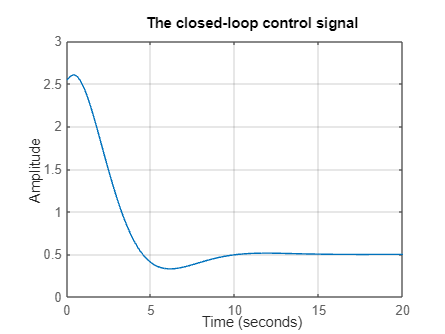

%Calculate the control signal
Upi=M/(1+L);
step(Upi,t),grid
title('The closed-loop control signal')


% Settling time of G: 41 sec
% Settling time of T: 8,6 sec
% overshoot: 8%

It is seen that there is no steady state error. There is a small overshoot. The settling time is about 9 sec.

#### 4.1.3 Design a PD controller (M) for the same process (G)

A PD compensator includes a zero so we can use this flexibility to cancel the second slowest pole in the system as shown in the code below. (In this way the -20dB/decade slope in the open loop Bode amplitude diagram is enlenghtened and the cut-off frequency could be located to higher frequencies. This means decreasing of the settling time.) The remaining d.o.f. is used to ensure a 60 degree phase margin. Because the compensator does not include an integral,  offset will occur but is not dealt with directly as there are no remaining d.o.f. to choose.

disp('DESIGN OF PD CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS')

DESIGN OF PD CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS


disp('Pole cancellation technique')

Pole cancellation technique


disp('The second biggest time constant is cancelled and a smaller time constant is introduced instead.')

The second biggest time constant is cancelled and a smaller time constant is introduced instead.


disp('The phase margin is set to ~60° by the gain of the controller.')

The phase margin is set to ~60° by the gain of the controller.


s=zpk('s');
disp('The process')

The process


G=2/((1+10*s)*(1+s)*(1+0.2*s))

G =
 
           1
  -------------------
  (s+0.1) (s+1) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


Kd=1;
M=Kd*(1+s)/(1+0.2*s);
L=zpk(minreal(M*G));

% Find and confirm the gain which gives a 60 degree PM
[mag1,phase,w]=bode(L);
disp('The gain of the controller is:')

The gain of the controller is:


Kd=margin(mag1,phase-60,w)

Kd = 8.3033

disp('Check the phase margin')

Check the phase margin


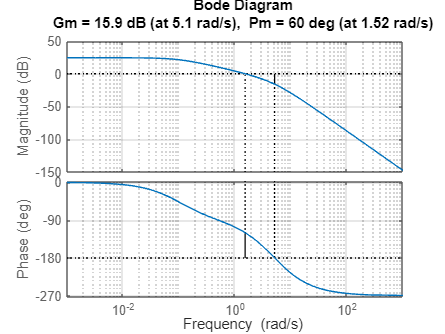

margin(L*Kd),grid


disp('The controller is:')

The controller is:


M=Kd*M

M =
 
  41.516 (s+1)
  ------------
     (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The open loop L=MG')

The open loop L=MG


L=L*Kd

L =
 
      41.516
  ---------------
  (s+5)^2 (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The closed loop T=L/(1+L)')

The closed loop T=L/(1+L)


T=minreal(L/(1+L),0.001)

T =
 
               41.516
  --------------------------------
  (s+7.387) (s^2 + 2.713s + 5.959)
 
Continuous-time zero/pole/gain model.
Model Properties


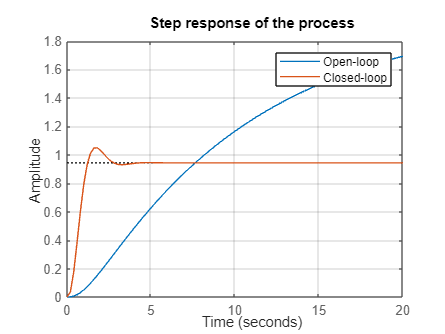

Lpd=L;


% Closed-loop behaviour
t=linspace(0,endtime,101);
yd=step(T,t);
step(G,T,t),grid
title('Step response of the process');
legend('Open-loop', 'Closed-loop');

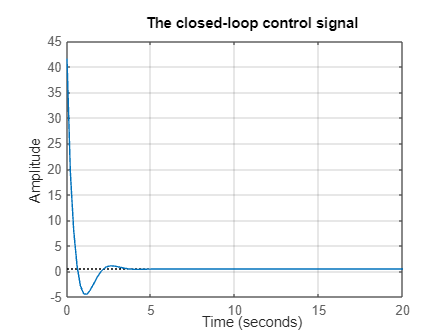

%Calculate the control signal
Upd=M/(1+L);
step(Upd,t),grid
title('The closed-loop control signal')


% Settling time of G: 41 sec
% Settling time of T: 2,6 sec
% overshoot: 11%

It is seen that the output of the control system is settled with a small overshoot. There is a deviation from the required steady state output as there is no integrator in the control circuit. The settling process became faster, because of the higher values of the control signal. The settling time is ~4 sec. 

Possible private study task: Calculate the output signal if there is a step output disturbance and the reference signal is zero.

#### 4.1.4 Design a PIPD controller (M) to the same process (G)

A PIPD compensator includes two zeros so we can use this flexibility to cancel the slowest pole and indeed the 2nd slowest should we so wish, as shown in the code below. The remaining d.o.f. is used to ensure a 60 degree phase margin. Because the compensator includes an integral,  offset is eliminated automatically.

disp('DESIGN OF A PIPD CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS')

DESIGN OF A PIPD CONTROLLER FOR A THIRD ORDER PROPORTIONAL PROCESS


disp('Pole cancellation technique')

Pole cancellation technique


disp('The first and the second biggest time constants are cancelled.')

The first and the second biggest time constants are cancelled.


disp('An integrating effect and a smaller time constants are introduced.')

An integrating effect and a smaller time constants are introduced.


disp('The phase margin is set to ~60° by the gain of the controller.')

The phase margin is set to ~60° by the gain of the controller.


s=zpk('s');
disp('The process')

The process


G=2/((1+10*s)*(1+s)*(1+0.2*s))

G =
 
           1
  -------------------
  (s+0.1) (s+1) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


K=1;
M = K*((1+10*s)/(10*s))*(1+s)/(1+0.2*s)

M =
 
  5 (s+0.1) (s+1)
  ---------------
      s (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


L = minreal(M*G,0.001);

%Calculating the gain of the controller
[mag,phase,w]=bode(L);
Gm=margin(mag,phase-60,w);
disp('Check the phase margin is about 60 degrees as desired')

Check the phase margin is about 60 degrees as desired


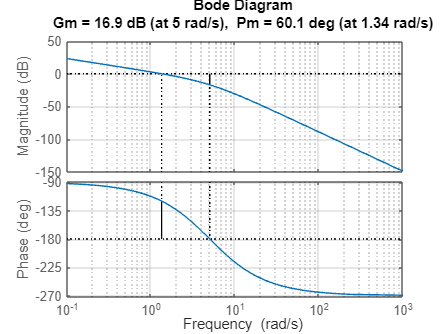

margin(L*Gm),grid


disp('The gain of the controller')

The gain of the controller


Kpid=Gm

Kpid = 7.1639

disp('The controller')

The controller


M = Kpid*M

M =
 
  35.82 (s+0.1) (s+1)
  -------------------
        s (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The open loop L=MG')

The open loop L=MG


L=L*Kpid

L =
 
    35.82
  ---------
  s (s+5)^2
 
Continuous-time zero/pole/gain model.
Model Properties


Lpid=L;

disp('The closed loop T=L/(1+L)')

The closed loop T=L/(1+L)


T=minreal(L/(1+L),0.001)

T =
 
               35.82
  --------------------------------
  (s+7.226) (s^2 + 2.774s + 4.957)
 
Continuous-time zero/pole/gain model.
Model Properties


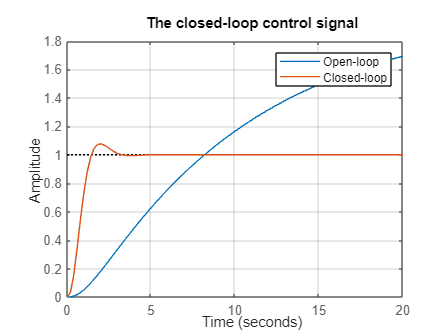

t=linspace(0,endtime,101);
step(G,T,t),grid
ypid=step(T,t);
title('Step responses of the process');
legend('Open-loop', 'Closed-loop');
%Calculate the control signal
Upipd=M/(1+L);
title('The closed-loop control signal')

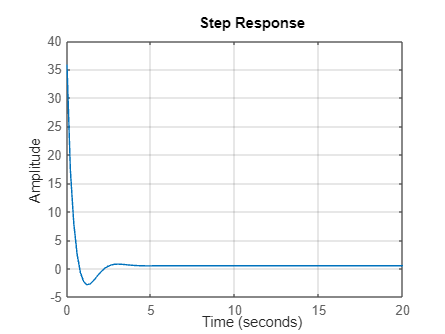

step(Upipd,t),grid

It is seen that the output of the control system is settled with a small overshoot. There is no steady state error. The settling process became faster, because of the higher values of the control signal. The settling time is ~4 sec.

#### 4.1.5 Comparison of P, PD, PI and PIPD

For comparison plot the outputs and Bode diagrams with the different controllers in one figure. One can see the different bandwidths achieved as well as the different low frequency gains. They all have the same phase margin of 60 degrees (the -120 degree line is marked for convenience so the varying cross over frequencies can be seen).

disp('Comparison of different pole cancellation techniques')

Comparison of different pole cancellation techniques


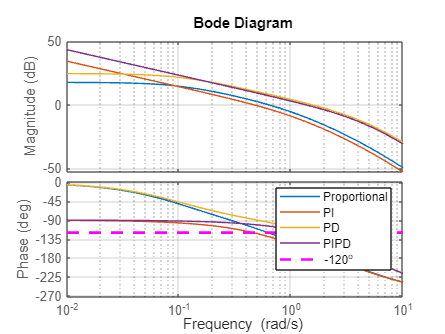


bode(Lkp,Lpi,Lpd,Lpid,{0.01,10});grid; hold on
plot([0.01,10],[-120,-120],'m--','linewidth',2)
legend('Proportional','PI','PD','PIPD','-120^o')
hold off

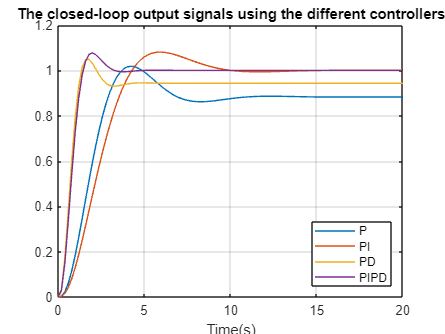


plot(t,yp,t,yi,t,yd,t,ypid),grid
title('The closed-loop output signals using the different controllers')
legend('P','PI','PD','PIPD','Location','Southeast')
xlabel('Time(s)')

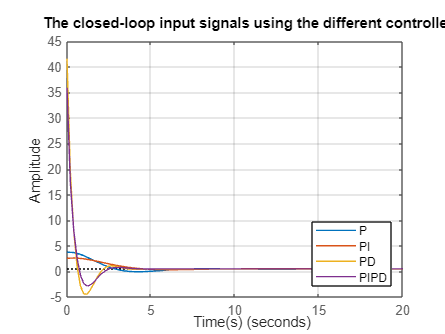


step(U,Upi,Upd, Upipd,t),grid
title('The closed-loop input signals using the different controllers')
legend('P','PI','PD','PIPD','Location','Southeast')
xlabel('Time(s)')

It is seen that the P and PI controllers provide a slow behaviour (lower cross-over frequencies) while with the PD and the PIPD controllers the settling process is faster. With the P and PD controllers there is a steady state deviation from the required value.

### 4.2 Controller design for a second order oscillating process

The transfer function of the process is


$$G\left(s\right)=\frac{A}{{T_0^{2\;} s}^2 +2\xi T_0 \;s+1}$$


Design a PIPD controller for the process ensuring a 60° phase margin using a pole cancellation technique. Show the output and the control signals for step reference input. Check the behaviour for different damping factor ($\xi$)  values. 

As the system is underdamped, the PIPD compensator aims to cancel the real part of what those poles would be with a damping ratio of 1, although of course such a cancellation is now approximate. that is: ${T_0^{2\;} s}^2 +2\xi T_0 \;s+1\to {T_0^{2\;} s}^2 +2T_0 \;s+1\to {\left(T_0 s+1\right)}^2$

% PID controller design for a second-order oscillating element
% The method is the same. Choose time constant Ti and Td equal to T0. 
% 
%            1+s*T0      1+s*T0 
% M(s) = K*---------- * ---------
%              s*T0      1+s*T
%
% To explore different damping factor values change the value kszi1 below

disp('DESIGN OF PIPD CONTROLLER FOR A SECOND ORDER OSCILLATING PROCESS')

DESIGN OF PIPD CONTROLLER FOR A SECOND ORDER OSCILLATING PROCESS



% Define the system model
disp('The process parameters and model')

The process parameters and model


endtime2 =30;
s=zpk('s');
kszi1=0.4

kszi1 = 0.4000

T0=3

T0 = 3

T=0.2

T = 0.2000

K=1

K = 1

G = 1.4/(s*s*T0*T0 + 2*kszi1*T0*s + 1)

G =
 
          0.15556
  ------------------------
  (s^2 + 0.2667s + 0.1111)
 
Continuous-time zero/pole/gain model.
Model Properties



% define the PIPD structure using the core model parameters
disp('Using the slowest time constant T0 as the choice to cancel (both occurrences)')

Using the slowest time constant T0 as the choice to cancel (both occurrences)


M = K*[(1+T0*s)/(T0*s)]*[(1+T0*s)/(1+s*T)];
L = minreal(M*G,0.001);

%Calculating the gain of the controller
disp('Choose the gain to achieve a 60 degree phase margin')

Choose the gain to achieve a 60 degree phase margin


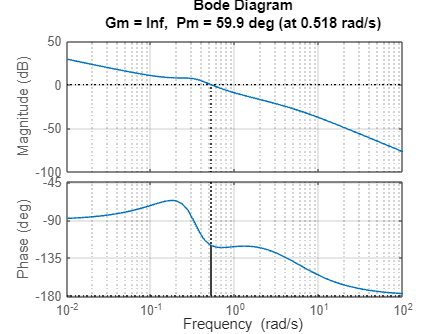

[mag,phase,w]=bode(L);
Gm=margin(mag,phase-60,w);
margin(L*Gm),grid


disp('The gain of the controller')

The gain of the controller


K=Gm

K = 0.6145

disp('The controller')

The controller


M = K*M

M =
 
  9.2168 (s+0.3333)^2
  -------------------
        s (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The open loop L=MG')

The open loop L=MG


L=L*K

L =
 
        1.4337 (s+0.3333)^2
  --------------------------------
  s (s+5) (s^2 + 0.2667s + 0.1111)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The closed loop T=L/(1+L)')

The closed loop T=L/(1+L)


T=minreal(L/(1+L),0.001)

T =
 
               1.4337 (s+0.3333)^2
  ---------------------------------------------
  (s+4.724) (s+0.1302) (s^2 + 0.4129s + 0.2591)
 
Continuous-time zero/pole/gain model.
Model Properties


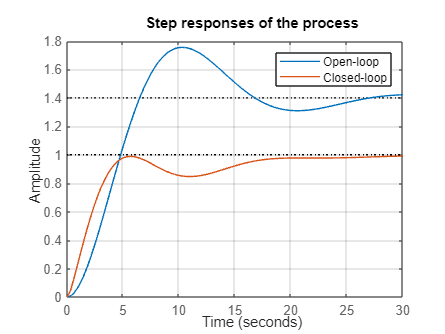


% Closed-loop behaviour
t=linspace(0,endtime2,101);
step(G,T,t),grid
title('Step responses of the process');
legend('Open-loop', 'Closed-loop');

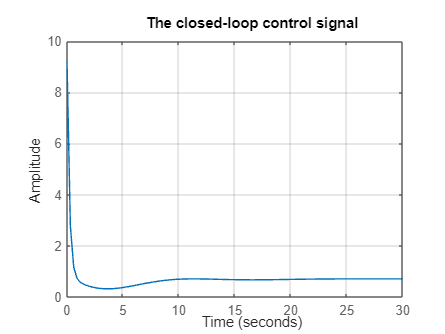

U=M/(1+L);
step(U,t),grid
title('The closed-loop control signal')

Possible task: Check the behaviour for different damping factors.

### 4.3 PI controller design for a dead time process

The transfer function of the process is


$$G\left(s\right)=\frac{2}{1+20s}e^{-10\;s}$$


Design a PI controller with pole cancellation technique. Ensure ~60° phase margin. Show the output and the control signals for step reference input. The main challenge in this case is that the delay is quite large and thus significant detuning will be required to meet the phase margin requirement due to the rapid decrease in phase with frequency.

Remark: The dead time modifies significantly the phase angle. 

% PI controller design for a dead time process
 
disp('DESIGN OF PI CONTROLLER FOR A DEAD TIME PROCESS')

DESIGN OF PI CONTROLLER FOR A DEAD TIME PROCESS


s=zpk('s');
disp('The process and the dead time')

The process and the dead time


Gp=2/(1+20*s)  

Gp =
 
    0.1
  --------
  (s+0.05)
 
Continuous-time zero/pole/gain model.
Model Properties


Td=10

Td = 10

kc=1;
delayfactor = exp(-10*s);

% disp('Nominal PI structure)
M=kc*(1+20*s)/(20*s);  
Lp=minreal(M*Gp,0.001);


% Achieving a 60 degree PM
% The dead time modifies the phase angle significantly

w=logspace(-2,1,100)';
[mag,phase]=bode(Lp,w);
magd=mag(:);
%Modify the phase angle with adding the phase angle of the dead time
phased=phase(:)-w*Td*180/pi;
gm=margin(magd,phased-60,w);
disp('Plot the Bode diagram with and without the delay')

Plot the Bode diagram with and without the delay


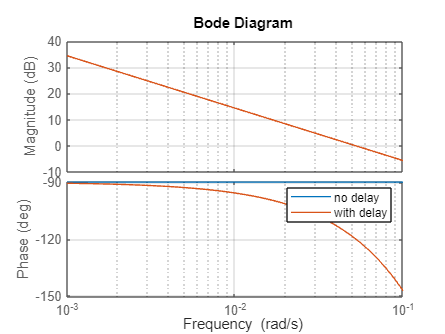

bode(Lp*gm,Lp*gm*delayfactor,{0.001,0.1}),legend('no delay','with delay'),grid

disp('Check the phase margin of the system with dead time')

Check the phase margin of the system with dead time


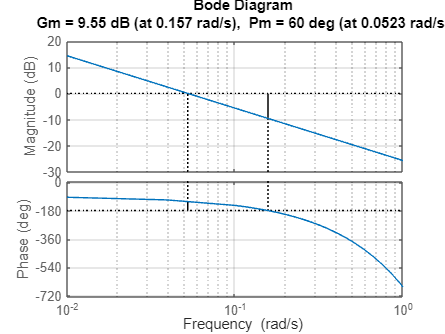

margin(Lp*gm*delayfactor),grid


disp('Choice of gain')

Choice of gain


kc=gm 					

kc = 0.5233

disp('The controller')

The controller


M=kc*M

M =
 
  0.52334 (s+0.05)
  ----------------
         s
 
Continuous-time zero/pole/gain model.
Model Properties


disp('Loop transfer function')

Loop transfer function


L=Lp*kc*delayfactor 

L =
 
               0.052334
  exp(-10*s) * --------
                  s
 
Continuous-time zero/pole/gain model.
Model Properties



%The closed loop
T=minreal(L/(1+L),0.001);

1 state removed.


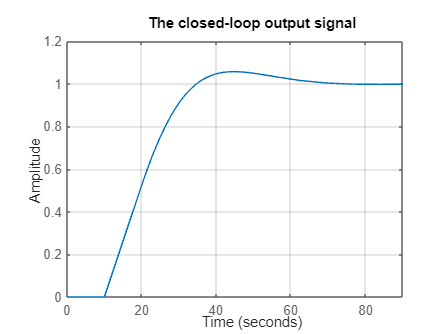


step(T),grid
title('The closed-loop output signal')

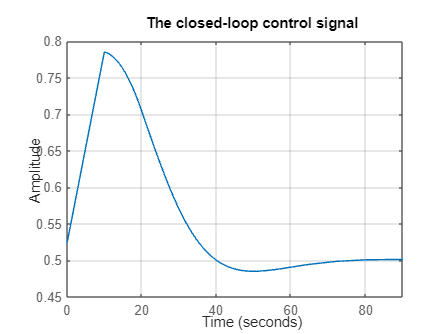

U=M/(1+L);
step(U),grid
title('The closed-loop control signal')

The cut-off frequency is at $\omega_c$=0.05233, the settling time is about $\frac{3}{\omega_c }$~60 sec. 

It is mentioned that in systems with dead time ensuring ~60° phase margin the cut-off frequency will be located approximately at $1/2T_d$ which in our case is 0.05. The dead time restricts the possible acceleration of the control system.